Formler at lære udenad

1.1, 1.3, 1.7, 1,12b) og c), 1.12e, 3.19 

simplified steady-flow thermal energy equation:

**Opgave 1.30**

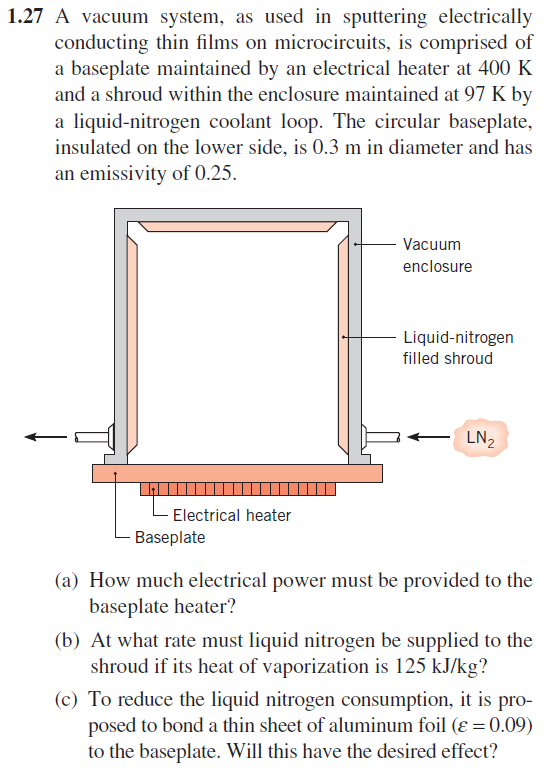

%a
T_heater = 400; %K
T_shroud = 97; %K
d=0.3; %m
epsilon = 0.25; %emesivitet
sigma = 5.67 * 10^-8; % J/K %stefan-boltzman konstant
A = pi*(d/2)^2;
q = A*epsilon * sigma * (T_heater^4 - T_shroud^4)

q = 25.5618


%b
l_f = 125000 %kJ/kg

l_f = 125000

%Q = m*L_f
m_dot = q/l_f %masse stræmmen kg/s

m_dot = 2.0449e-04


m_dot_hours = m_dot * 60 * 60

m_dot_hours = 0.7362

supplie 0,205 gram per s or 0,7362 kg per time

%c
epsilon_alu = 0.09

epsilon_alu = 0.0900

q_alu = q * (epsilon_alu/epsilon) % vi tager og divdere q med epsilon og ganger med epsilon alu istedet.

q_alu = 9.2022


m_dot = q_alu/l_f %masse stræmmen kg/s

m_dot = 7.3618e-05


m_dot_hours = m_dot * 60 * 60

m_dot_hours = 0.2650

**Opgave 1.48**

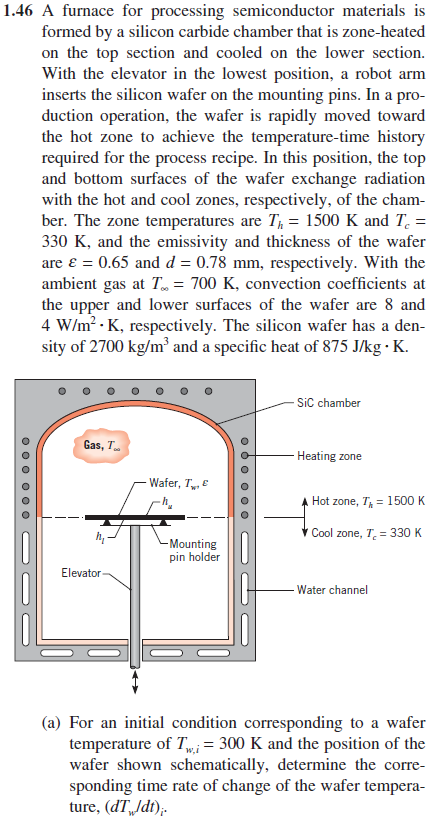

ASSUMPTIONS: 

(1) Wafer temperature is uniform, 

(2) Transient conditions when wafer is initially positioned, 

(3) Hot and cool zones have uniform temperatures, 

(4) Radiation exchange is between small surface (wafer) and large enclosure (chamber, hot or cold zone),

(5) Negligible heat losses from wafer to mounting pin holder.

clear all
T_h = 1500; %K
T_c = 330; %K
epsilon = 0.65; % from wafer
d = 0.78 *1e-3; %thickness of wafer %m
T_amb = 700 %K

T_amb = 700

sigma = 5.67 * 10^-8; % J/K
h_up = 8 % W/m^2*K

h_up = 8

h_low = 4 % W/m^2*K

h_low = 4


rho_SiC = 2700; % kg/m^3
c_p =  875; % J/kg*K

T_wi = 300; %K

q_con_h = h_up * (T_wi - T_amb) %convection above plate

q_con_h = -3200

q_con_l = h_low * (T_wi- T_amb) %convection below plate

q_con_l = -1600

q_rad_h = epsilon * sigma * (T_h^4 - T_wi^4) %radiation above plate

q_rad_h = 1.8628e+05

q_rad_l = epsilon * sigma * (T_c^4 - T_wi^4) %radiation below plate

q_rad_l = 138.5457


q_mark = - q_con_h - q_con_l + q_rad_h + q_rad_l

q_mark = 1.9122e+05

dTdt = q_mark / (rho_SiC * c_p * d)

dTdt = 103.7680

vpa(dTdt, 4)

$$ans = 103.8$$

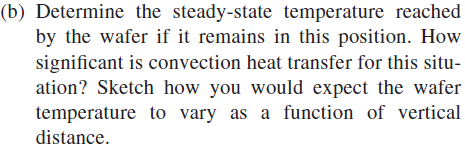

syms T_wi
q_con_h = h_up * (T_wi - T_amb); %convection above plate
q_con_l = h_low * (T_wi- T_amb); %convection below plate
q_rad_h = epsilon * sigma * (T_h^4 - T_wi^4); %radiation above plate
q_rad_l = epsilon * sigma * (T_c^4 - T_wi^4); %radiation below plate
q_mark = - q_con_h - q_con_l + q_rad_h + q_rad_l;
dTdt_eq = 0 == q_mark / (rho_SiC * c_p * d);

T_wi_steady = vpa(solve(dTdt_eq, T_wi),5)

$$T\_wi\_steady = \left(\begin{array}{c} 1250.8\\ 25.003-1276.3\,\mathrm{i}\\ 24.996+1276.3\,\mathrm{i}\\ -1300.8 \end{array}\right)$$

Her bruger vi den reele løsning der er positiv 1251 K

3.28

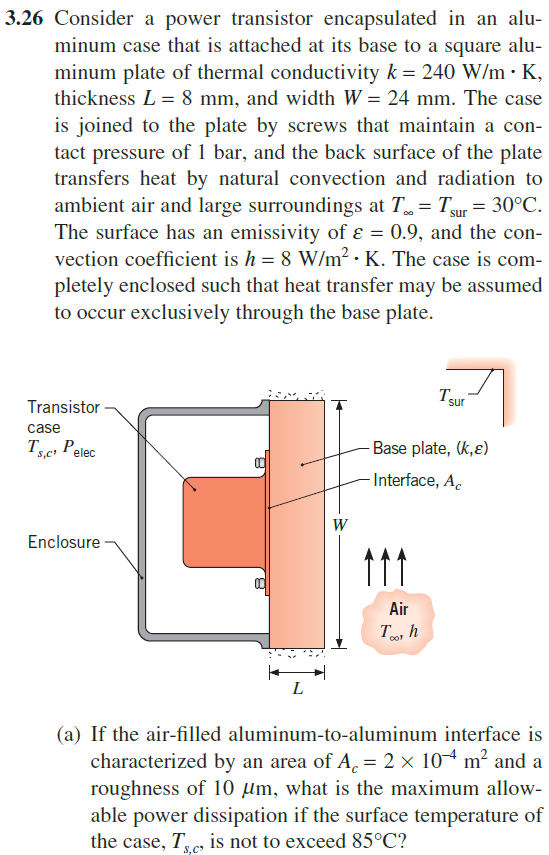

clear all

k = 240; % W/(m*K)
L = 0.008; %m %længde
W = 0.024;%m
T_inf = 30+273.15; % K
T_sur = T_inf;
epsilon = 0.9;
h = 8; % W/(M^2 * K) 
A_plate = W^2; % Area of square plate
A_c =2e-4;
mu = 10e-6;
T_sc = 85 + 273.15; %K
sigma = 5.670374419 * 10^-8; % J/K %stefan-boltzman konstant
R_tc = 2.75e-4; %m^2 * K/ W % Thermal Resistance fra Table 3.1 side 106 (husk det er 10^-4)

 * A

 * A

Det antages at varmen spredes instantat til hele højden af pladen og derefter går igennem pladen.

Da vi har steady state er q ens igennem alle modstande.

steady state dT/dt = 0 

(1) Steady-state, (2) Negligible heat transfer from the enclosure, to the

surroundings. (3) One-dimensional conduction in the base plate, (4) Radiation exchange at surface of

base plate is with large surroundings, (5) Constant thermal conductivity.

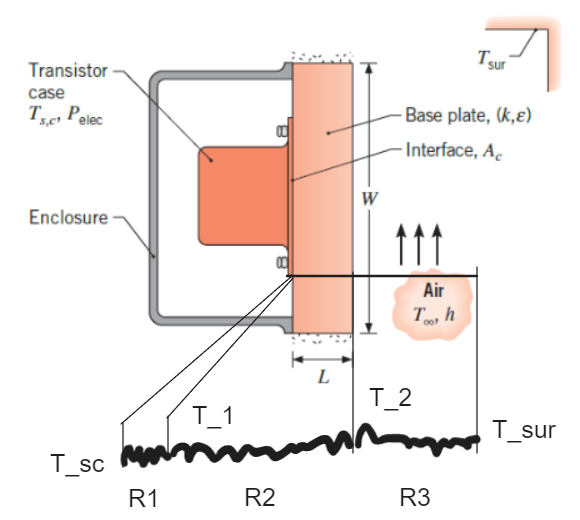

syms T_1 T_2 q T_var
T_2 = sym("T_2", "real");
T_2 = sym("T_2", "positive");


h_r = epsilon * sigma * (T_2 +T_sur) * (T_2^2 +T_sur^2); %ligning 1.9

% q_saml = (T_sc - T_1)/R_tc
% q_cond = -k*A_plate/L * (T_1 - T_2)

R1 = R_tc/A_c %modstanden af plade samlingen

R1 = 1.3750

R2 = L/(k *A_plate) %modstanden igennem pladen

R2 = 0.0579

Vi samler de to ligninger således vi eliminere $T_1$

q_smal_cond_eq = (T_sc - T_2)/ (R1 + R2);

q_conv = h * A_plate * (T_2 - T_inf);
q_rad = epsilon * sigma * (T_2^4 - T_sur^4) * A_plate; % = h_r * A_plate * (T_2 - T_sur) % 

R3 er paralel forbindelse imellem R3_conv og R3_rad

R3_conv = 1/(h*A_plate);
R3_rad = 1/(h_r*A_plate);
R3 = 1/(1/R3_conv + 1/R3_rad);

q_conv_rad_eq  = q_conv + q_rad % = (T_2 - T_inf)/ R3

$$q\_conv\_rad\_eq = \frac{69407503175365443\,{T_{2}}^{4}}{2361183241434822606848000000}+\frac{72\,T_{2}}{15625}-\frac{20366284418783428455829683106813593}{12379400392853802748991242240000000}$$

Vi siætter de to fundne ligninger lig med hinanden

T_2_sol = solve(q_smal_cond_eq == q_conv_rad_eq, T_2);
T_2_sol_ = vpa(T_2_sol, 5)% - 273.75

$$T\_2\_sol\_ = 357.46$$


q = (T_sc - T_sur)/(R1 + R2 + subs(R3, T_2, T_2_sol));

P_elec = vpa(q,5)

$$P\_elec = 0.48193$$

h_lin = linspace(4,200, 200-3);
T_2_sol = [];
qs = [];

for i = 1:length(h_lin)
    q_conv = h_lin(i) * A_plate * (T_2 - T_inf);
    q_conv_rad_eq  = q_conv + q_rad; % = (T_2 - T_inf)/ R3

    T_2_sol(i) = solve(q_smal_cond_eq == q_conv_rad_eq, T_2);
    % vpa(T_2_sol, 5)% - 273.75
    
    qs(i) = (T_sc - T_sur)/(R1 + subs(R2, h, h_lin(i)) + subs(R3, T_2, T_2_sol(i)));
end

sanity_check_q = qs(5)

sanity_check_q = 0.4819

sanity_check_h_lin = h_lin(5)

sanity_check_h_lin = 8

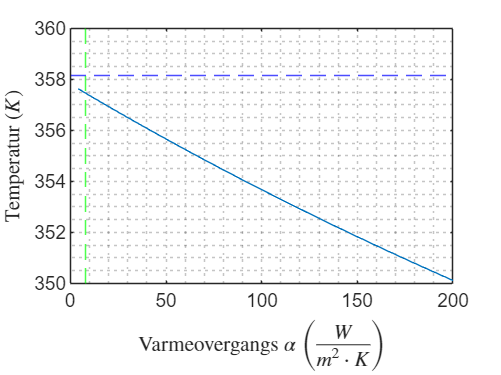


plot(h_lin, T_2_sol)
grid('minor')
yline(T_sc, 'b--')
xline(h,'g--')
xlabel("Varmeovergangs $\alpha$ $\left(\frac{W}{m^2 \cdot K}\right)$", Interpreter="latex")
ylabel("Temperatur $(K)$", Interpreter="latex")

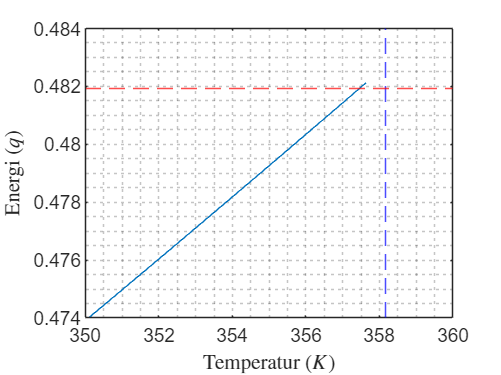


plot(T_2_sol, qs)
grid('minor')
xline(T_sc, 'b--')
yline(double(P_elec), 'r--')
ylabel("Energi $(q)$", Interpreter="latex")
xlabel("Temperatur $(K)$", Interpreter="latex")

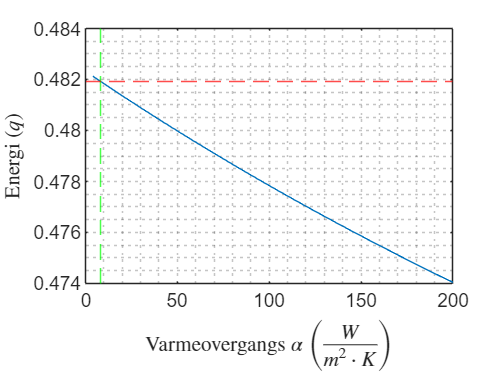


plot(h_lin, qs)
grid('minor')
xline(h,'g--')
yline(double(P_elec), 'r--')
ylabel("Energi $(q)$", Interpreter="latex")
xlabel("Varmeovergangs $\alpha$ $\left(\frac{W}{m^2 \cdot K}\right)$", Interpreter="latex")

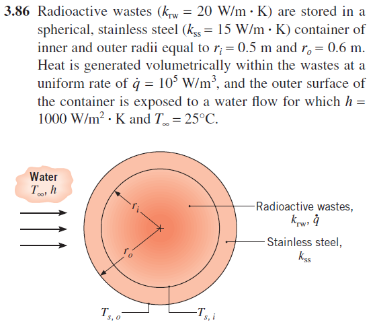

clear all
clf
k_rw = 20; % W/m*K
K_ss = 15; % W/m*K
r_i = 0.5; %m
r_o = 0.6; % m
q_dot = 1e5; % W/m^3
h = 1000; % W/m^2*K
T_inf = 25 + 273.15; % K

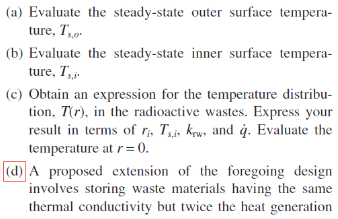

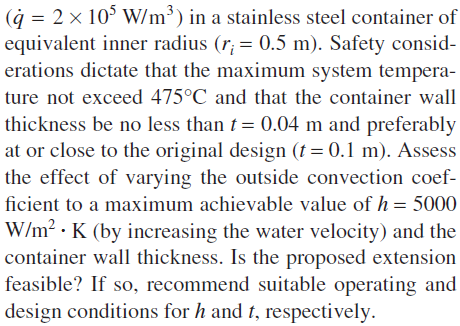

(a)

Bruger Gauss's law  eqvivalent


$$q(r) = \int \dot q\ dV = \dot q  \frac{4}{3} \pi r^3$$


Vi finder T_s,o ved at gå igennem film laget hvor den totale varme der kommer ud er q genneret af kernen

syms T_s
assume(T_s, 'real')

q = q_dot * 4/3 * pi * r_i;
A_o = pi*r_o^2;
q_conv = h*A_o *(T_s - T_inf);

T_s_ = solve(q == q_conv, T_s);
T_s = double(vpa(T_s_, 6))

T_s = 483.3352

T_s_C = T_s - 273.15

T_s_C = 210.1852

(b)